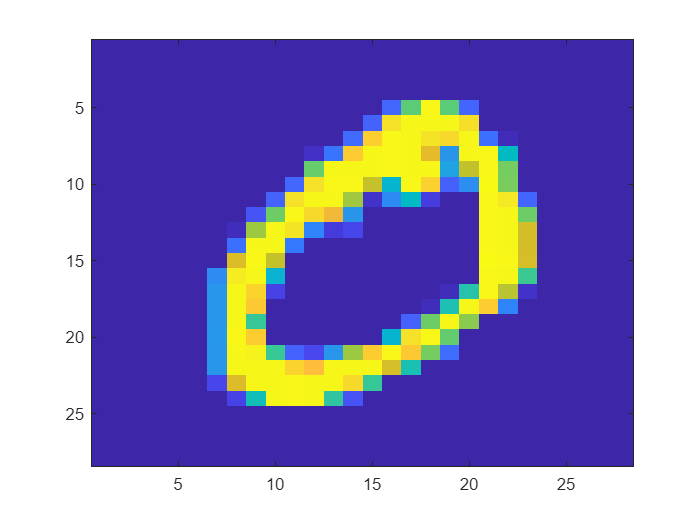

%Loading the dataset
load('../../data/mnist.mat');
axis equal
count = 0;
digits= zeros(28,28,1); %Matrix to store the data for each digit
for i=1:60000
    if labels_train(i) == 0  %For the digit 0
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double'); %Casting to make the integers into floating point 
data_matrix = reshape(digits,28*28,count); %Reshaping to get a 784x1 coulumn vector for each image
mean_vector = sum(data_matrix,2)/count; %Calculating the mean vector
mean_matrix = ones(28*28,count); %Mean matrix i.e. each column is the mean vector
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1); %Calculating the covariance matrix
H = (data_matrix-mean_matrix)/sqrt(count-1); %Defining H matrix so as to calculate eigen vectors using H*H' which gives only real values
[V,D] = eig(H*H'); %Calculating this way because other ways might give complex eigen vectors due to numerical errors 
[~,ind] = sort(abs(diag(D)));
coordinates = sort(ind(1:84,1)); %The coordinates of the top 84 eigenvalues(The function is also written in compute.m) 
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
D_sorted = D(ind,ind);
V_sorted = V(:,ind);
V_compressed = V_sorted(:,1:84); %The matrix with the top 84 eigenvectors
Projection = ((data_matrix-mean_matrix).')*V_compressed; %Projection of the data on a lower dimension basis 
Reprojection = (Projection * V_compressed.').'; %Getting the reprojection of the compressed data on the standard basis
imagesc(reshape(digits(:,:,1),28,28)); %The original image

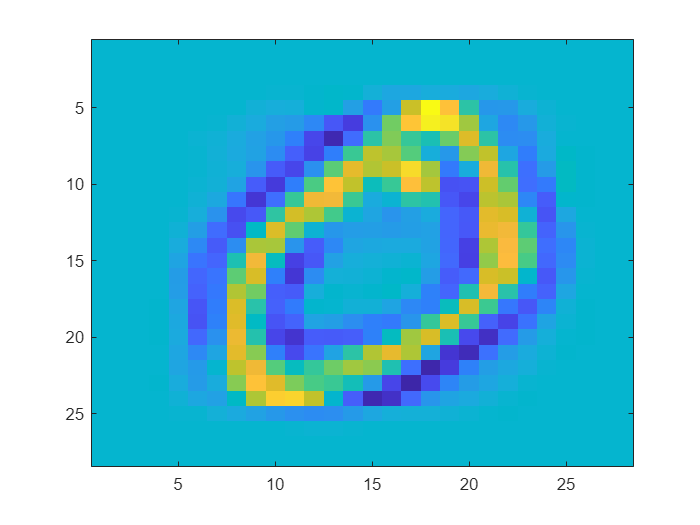

imagesc(reshape(Reprojection(:,1),28,28)); %The reconstructed image

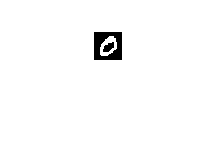

imshow((reshape(digits(:,:,1),28,28))); %The original image greyscale

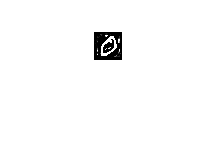

imshow((reshape(Reprojection(:,1),28,28))); %The reconstructed image greyscale

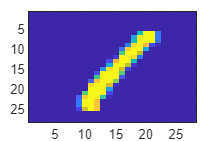


%Doing the same for the other digits

%For the digit 1
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 1
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double');
data_matrix = reshape(digits,28*28,count);
mean_vector = sum(data_matrix,2)/count;
mean_matrix = ones(28*28,count);
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1);
H = (data_matrix-mean_matrix)/sqrt(count-1);
[V,D] = eig(H*H');
[~,ind] = sort(abs(diag(D)));
coordinates = sort(ind(1:84,1));
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
D_sorted = D(ind,ind);
V_sorted = V(:,ind);
V_compressed = V_sorted(:,1:84);
Projection = ((data_matrix-mean_matrix).')*V_compressed;
Reprojection = (Projection * V_compressed.').';
imagesc(reshape(digits(:,:,1),28,28));

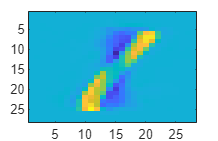

imagesc(reshape(Reprojection(:,1),28,28));

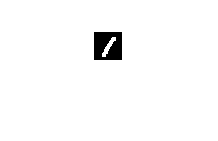

imshow((reshape(digits(:,:,1),28,28)));

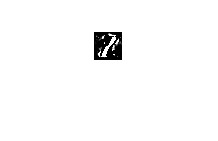

imshow((reshape(Reprojection(:,1),28,28)));

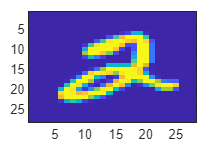


%For the digit 2
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 2
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double');
data_matrix = reshape(digits,28*28,count);
mean_vector = sum(data_matrix,2)/count;
mean_matrix = ones(28*28,count);
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1);
H = (data_matrix-mean_matrix)/sqrt(count-1);
[V,D] = eig(H*H');
[~,ind] = sort(abs(diag(D)));
coordinates = sort(ind(1:84,1));
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
D_sorted = D(ind,ind);
V_sorted = V(:,ind);
V_compressed = V_sorted(:,1:84);
Projection = ((data_matrix-mean_matrix).')*V_compressed;
Reprojection = (Projection * V_compressed.').';
imagesc(reshape(digits(:,:,1),28,28));

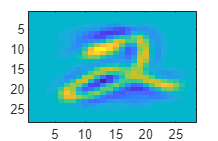

imagesc(reshape(Reprojection(:,1),28,28));

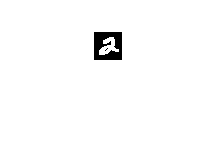

imshow((reshape(digits(:,:,1),28,28)));

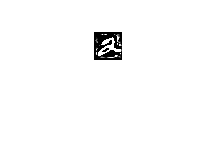

imshow((reshape(Reprojection(:,1),28,28)));

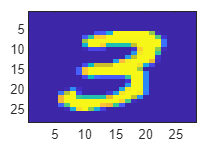


%For the digit 3
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 3
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double');
data_matrix = reshape(digits,28*28,count);
mean_vector = sum(data_matrix,2)/count;
mean_matrix = ones(28*28,count);
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1);
H = (data_matrix-mean_matrix)/sqrt(count-1);
[V,D] = eig(H*H');
[~,ind] = sort(abs(diag(D)));
coordinates = sort(ind(1:84,1));
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
D_sorted = D(ind,ind);
V_sorted = V(:,ind);
V_compressed = V_sorted(:,1:84);
Projection = ((data_matrix-mean_matrix).')*V_compressed;
Reprojection = (Projection * V_compressed.').';
imagesc(reshape(digits(:,:,1),28,28));

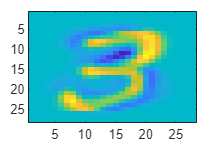

imagesc(reshape(Reprojection(:,1),28,28));

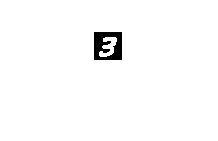

imshow((reshape(digits(:,:,1),28,28)));

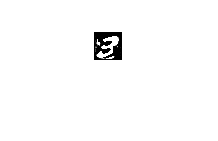

imshow((reshape(Reprojection(:,1),28,28)));

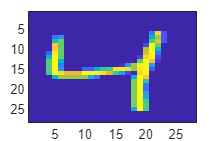


%For the digit 4
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 4
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double');
data_matrix = reshape(digits,28*28,count);
mean_vector = sum(data_matrix,2)/count;
mean_matrix = ones(28*28,count);
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1);
H = (data_matrix-mean_matrix)/sqrt(count-1);
[V,D] = eig(H*H');
[~,ind] = sort(abs(diag(D)));
coordinates = sort(ind(1:84,1));
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
D_sorted = D(ind,ind);
V_sorted = V(:,ind);
V_compressed = V_sorted(:,1:84);
Projection = ((data_matrix-mean_matrix).')*V_compressed;
Reprojection = (Projection * V_compressed.').';
imagesc(reshape(digits(:,:,1),28,28));

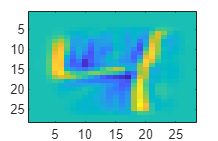

imagesc(reshape(Reprojection(:,1),28,28));

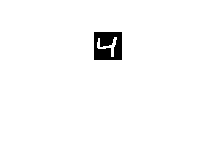

imshow((reshape(digits(:,:,1),28,28)));

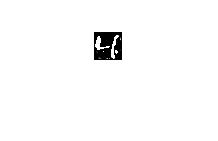

imshow((reshape(Reprojection(:,1),28,28)));

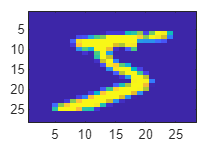



%For the digit 5
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 5
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double');
data_matrix = reshape(digits,28*28,count);
mean_vector = sum(data_matrix,2)/count;
mean_matrix = ones(28*28,count);
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1);
H = (data_matrix-mean_matrix)/sqrt(count-1);
[V,D] = eig(H*H');
[~,ind] = sort(abs(diag(D)));
coordinates = sort(ind(1:84,1));
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
D_sorted = D(ind,ind);
V_sorted = V(:,ind);
V_compressed = V_sorted(:,1:84);
Projection = ((data_matrix-mean_matrix).')*V_compressed;
Reprojection = (Projection * V_compressed.').';
imagesc(reshape(digits(:,:,1),28,28));

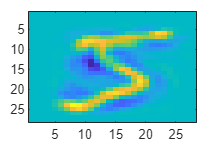

imagesc(reshape(Reprojection(:,1),28,28));

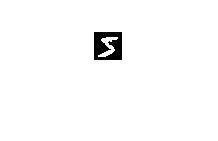

imshow((reshape(digits(:,:,1),28,28)));

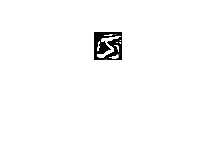

imshow((reshape(Reprojection(:,1),28,28)));

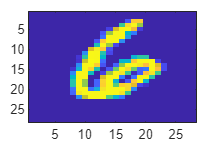



%For the digit 6
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 6
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double');
data_matrix = reshape(digits,28*28,count);
mean_vector = sum(data_matrix,2)/count;
mean_matrix = ones(28*28,count);
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1);
H = (data_matrix-mean_matrix)/sqrt(count-1);
[V,D] = eig(H*H');
[~,ind] = sort(abs(diag(D)));
coordinates = sort(ind(1:84,1));
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
D_sorted = D(ind,ind);
V_sorted = V(:,ind);
V_compressed = V_sorted(:,1:84);
Projection = ((data_matrix-mean_matrix).')*V_compressed;
Reprojection = (Projection * V_compressed.').';
imagesc(reshape(digits(:,:,1),28,28));

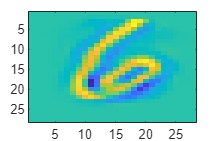

imagesc(reshape(Reprojection(:,1),28,28));

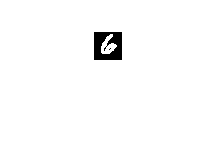

imshow((reshape(digits(:,:,1),28,28)));

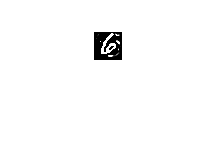

imshow((reshape(Reprojection(:,1),28,28)));

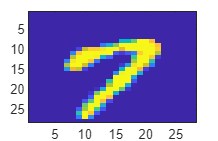


%For the digit 7
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 7
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double');
data_matrix = reshape(digits,28*28,count);
mean_vector = sum(data_matrix,2)/count;
mean_matrix = ones(28*28,count);
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1);
H = (data_matrix-mean_matrix)/sqrt(count-1);
[V,D] = eig(H*H');
[~,ind] = sort(abs(diag(D)));
coordinates = sort(ind(1:84,1));
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
D_sorted = D(ind,ind);
V_sorted = V(:,ind);
V_compressed = V_sorted(:,1:84);
Projection = ((data_matrix-mean_matrix).')*V_compressed;
Reprojection = (Projection * V_compressed.').';
imagesc(reshape(digits(:,:,1),28,28));

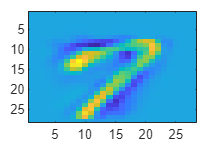

imagesc(reshape(Reprojection(:,1),28,28));

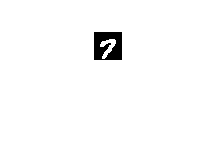

imshow((reshape(digits(:,:,1),28,28)));

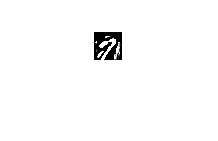

imshow((reshape(Reprojection(:,1),28,28)));

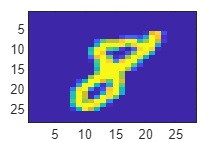



%For the digit 8
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 8
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double');
data_matrix = reshape(digits,28*28,count);
mean_vector = sum(data_matrix,2)/count;
mean_matrix = ones(28*28,count);
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1);
H = (data_matrix-mean_matrix)/sqrt(count-1);
[V,D] = eig(H*H');
[~,ind] = sort(abs(diag(D)));
coordinates = sort(ind(1:84,1));
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
D_sorted = D(ind,ind);
V_sorted = V(:,ind);
V_compressed = V_sorted(:,1:84);
Projection = ((data_matrix-mean_matrix).')*V_compressed;
Reprojection = (Projection * V_compressed.').';
imagesc(reshape(digits(:,:,1),28,28));

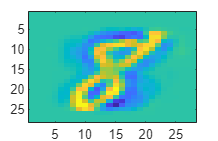

imagesc(reshape(Reprojection(:,1),28,28));

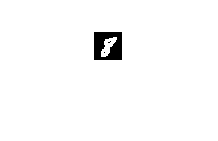

imshow((reshape(digits(:,:,1),28,28)));

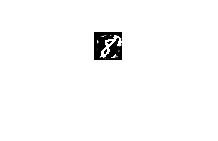

imshow((reshape(Reprojection(:,1),28,28)));

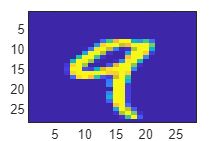



%For the digit 9
count = 0;
digits= zeros(28,28,1);
for i=1:60000
    if labels_train(i) == 9
        count = count+1;
        digits(:,:,count) = digits_train(:,:,i);
    end
end
digits= cast(digits,'double');
data_matrix = reshape(digits,28*28,count);
mean_vector = sum(data_matrix,2)/count;
mean_matrix = ones(28*28,count);
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1);
H = (data_matrix-mean_matrix)/sqrt(count-1);
[V,D] = eig(H*H');
[~,ind] = sort(abs(diag(D)));
coordinates = sort(ind(1:84,1));
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
D_sorted = D(ind,ind);
V_sorted = V(:,ind);
V_compressed = V_sorted(:,1:84);
Projection = ((data_matrix-mean_matrix).')*V_compressed;
Reprojection = (Projection * V_compressed.').';
imagesc(reshape(digits(:,:,1),28,28));

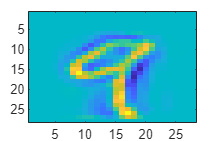

imagesc(reshape(Reprojection(:,1),28,28));

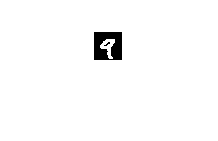

imshow((reshape(digits(:,:,1),28,28)));

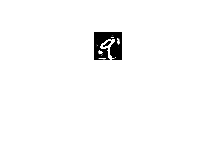

imshow((reshape(Reprojection(:,1),28,28)));